# **Native Modbus TCP Multi-Node Loopback**

This example demonstrates how one Modbus TCP Client and three Modbus TCP Servers communicate.

All the Modbus nodes are in the same system and on the same Ethernet interface. This is achieved by assigning multiple alias-IP addresses to one Ethernet interface. With this setup, the Modbus TCP Client and Servers are on the same physical Ethernet interface. Server 0 provides a multi-unit server whereas servers 1 and 2 are single-unit servers with separate data tables.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with at least one unused Ethernet interface

- "Runtime License File" for Modbus TCP Client (if purchased) and Server(s). Refer to the [Runtime Licensing](https://www.speedgoat.com/help/slrt/page/io_main/refentry_runtime_license) documentation for more information

### Wiring of Target Machine

No physical wiring is required.

### Ethernet Configuration of the Client and Servers

Use the **Speedgoat Ethernet Configuration Tool** to assign the IP address to one unused Ethernet interface (on-board or IO71x/IO79x) on the target machine. The communication between the client and the server(s) on the unused Ethernet interface is performed over the localhost. No cable is required.

 
% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% To configure the Ethernet interface for the example use this command below to open the API
speedgoat.configureEthernet; % Do not mind the picture below created after the execution of this command. There is no way to inhibit this output.

The IP address assigned should be `192.168.10.1`. The netmask for this local address is `255.255.255.0`. This IP is used as the gateway address for the client and server(s) in this example.

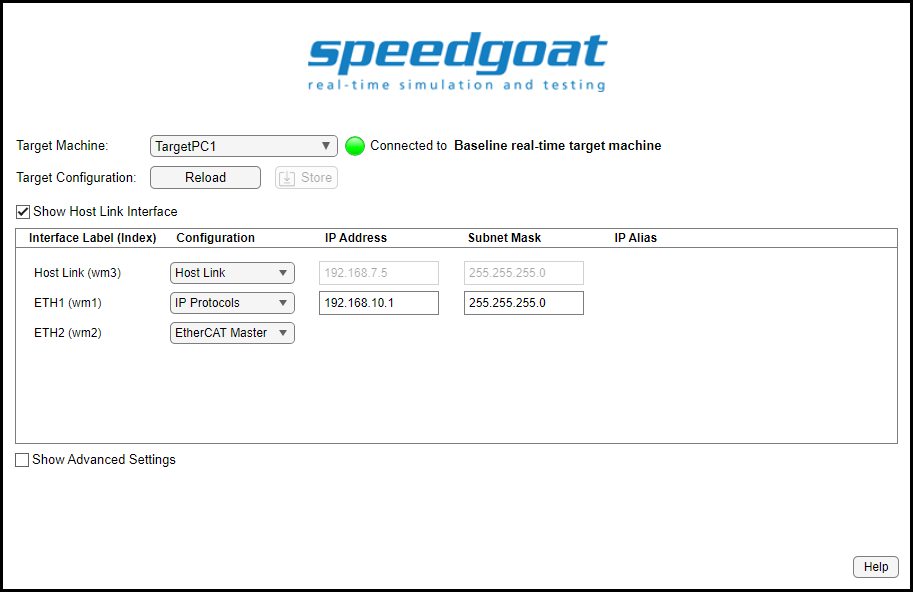

Add the IP addresses of the client and server(s) to the same Ethernet interface. Adapt the name of the interface according to your machine configuration.

 
IP_Client_00 = '192.168.10.10';
IP_Server_00 = '192.168.10.20';
IP_Server_01 = '192.168.10.21';
IP_Server_02 = '192.168.10.22';

InterfaceName = 'ETH1'; % Ethernet Interface on the target machine used for this example. Adapt this according to your machine.
ipAliasObj = speedgoat.IpAliasConfiguration('TargetObject', tg);
ipAliasObj.add(InterfaceName, {IP_Client_00, IP_Server_00, IP_Server_01, IP_Server_02});

Check the server Ethernet settings:

ipAliasObj.show();

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_ModbusTCP_1CLI3SRV';
open_system(modelName);

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download the real-time application to the target machine
tg.load(modelName);

% Start the real-time application and open the SDI-Viewer
stoptime = 32; % Simulation length [s]
numsignals = 12; % Number of signals to be viewed in the SDI

Simulink.sdi.clearAllSubPlots;
Simulink.sdi.view;

tg.setStopTime(stoptime);
tg.start;

runobj = Simulink.sdi.Run.getLatest;
sigsobj = runobj.getAllSignals;
for k = 1:numsignals % Display all signals in the plot
    sigsobj(k).Checked = 1;
end

pause(1)
Simulink.sdi.setSubplotLimits(1, 1, "tMin", 0, "tMax", stoptime, "yMin", -85, "yMax", 85);

The output is then visible in the Simulink Data Inspector (SDI). You should see 8 sine waves, like in the image below:

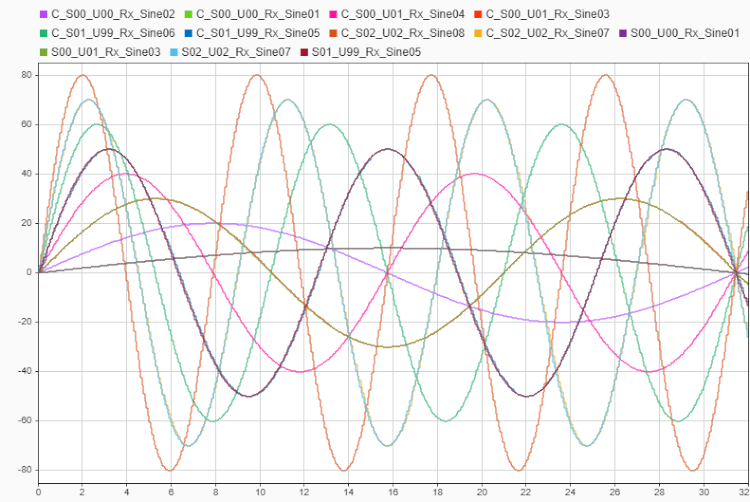

Some of the sine waves are superposed, this is to verify consitency of the signals.

## Restore Target Machine Configuration

To restore the default configuration, you can simply reopen the **Speedgoat Ethernet Configuration Tool** and tick the **Show Advanced Settings** checkbox. Then click the **Restore** button in the bottom right.

This will erase the IPs of every Ethernet interface and set the host link IP to 192.168.7.5 and the netmask to 255.255.255.0.

We recommend restoring the default settings to reduce possible configuration errors.

## Additional References

- [Modbus TCP Client documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_mbtcp_client)

- [Modbus TCP Server documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_mbtcp_server)